 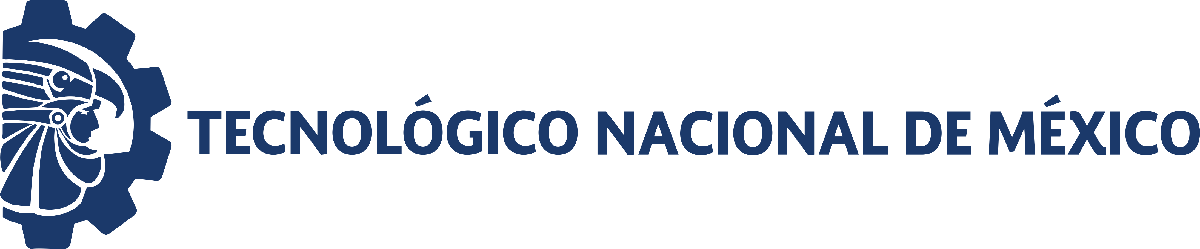                                 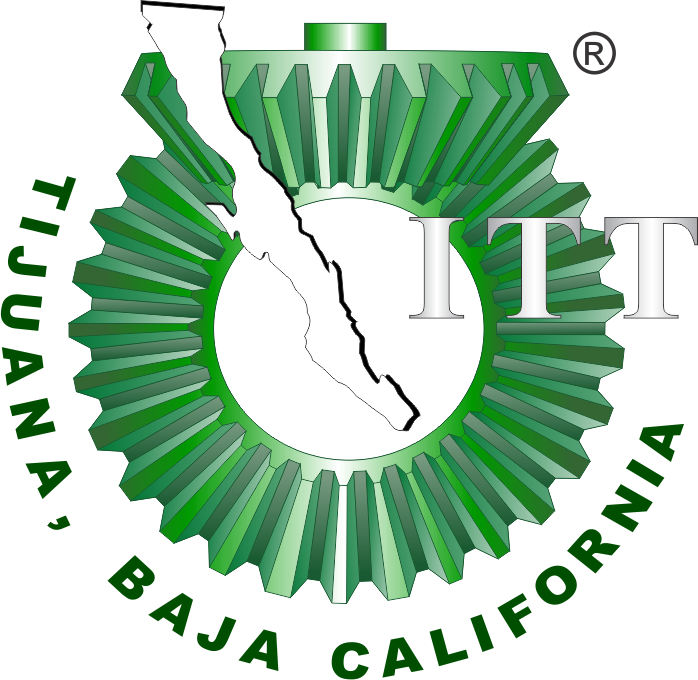

# Práctica 2: Sistema presa-depredador de Lotka-Volterra

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

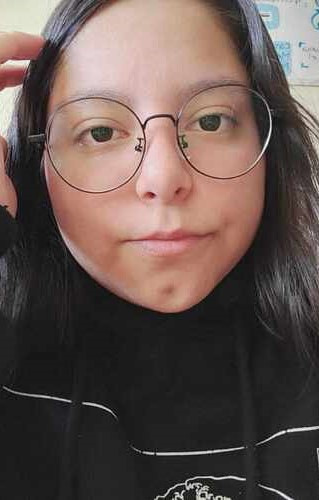

Nombre del alumno: **Diana Ivana Escalante Esquivel**

Número de control: **21212151**

Correo institucional: **L21212151@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Objetivo

Solucionar las ecuaciones de Lotka-Volterra para estudiar e ilustrar su dinámica en series de tiempo y el plano de fase. El sistema presa-depredador se formula mediante las siguientes dos EDOs de primer orden:


$$\dot{x} =\alpha x-\beta \textrm{xy}$$



$$\dot{y} =\delta \textrm{xy}-\gamma y$$


con los valores de los parámetros $\alpha =0\ldotp 5$, $\beta =0\ldotp 01$, $\delta =0\ldotp 005$, $\gamma =0\ldotp 2$, y las condiciones iniciales $x\left(0\right)=x_0 =75$ y $y\left(0\right)=y_0 =75$.

[Figura representativa del sistema elaborado en Biorender]

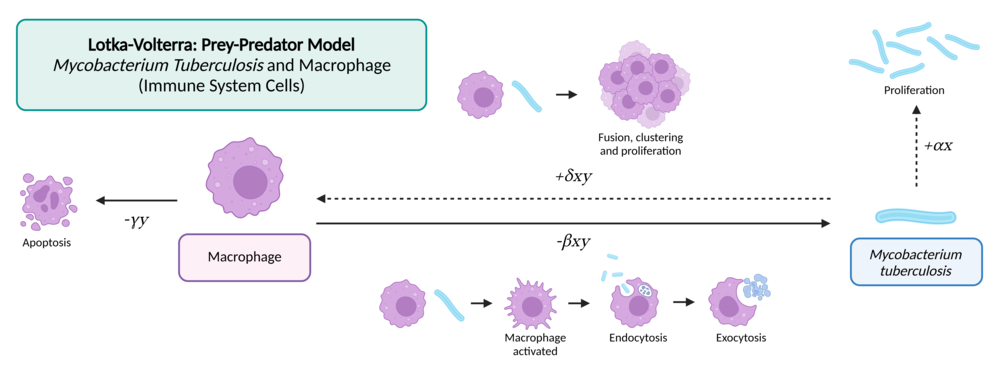

Figure. Macrophages encounter *Mycobacterium Tuberculosis; *these encounters result in both the eradication [negative feedback] of bacterias at a rate β, and the expansion [positive feedback] of immune system cells at a rate δ. Additionaly, macrophages die [exponential decay] at a rate given by γ, and bacterias grow [exponential growth] at a rate denoted by α.

## Simulation data

clc; clear; close all; warning('off','all')

## Parameters and initial conditions

alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
P = [alpha,beta,delta,gamma];
x0 = 75; y0 = 75; tend = 100;

## Solution by Euler's method

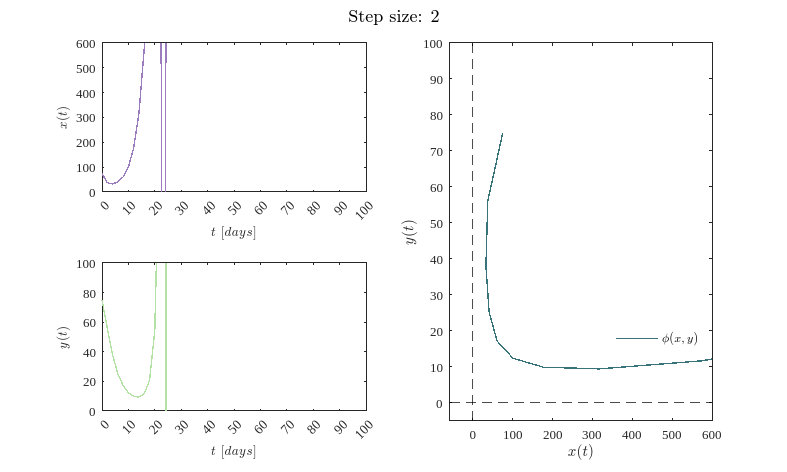

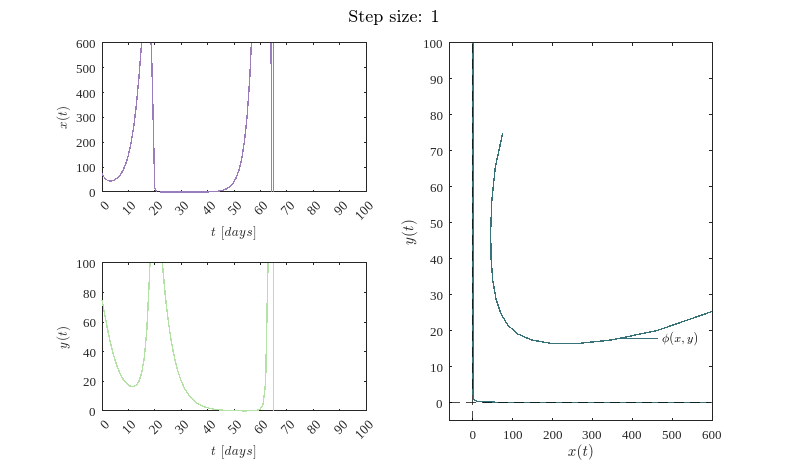

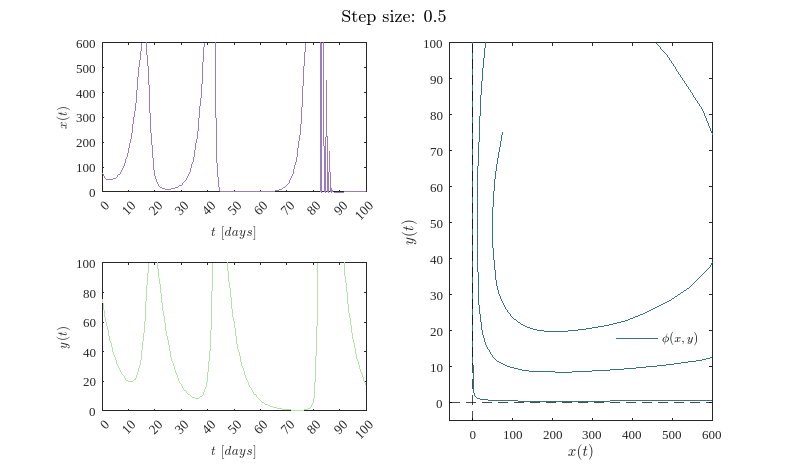

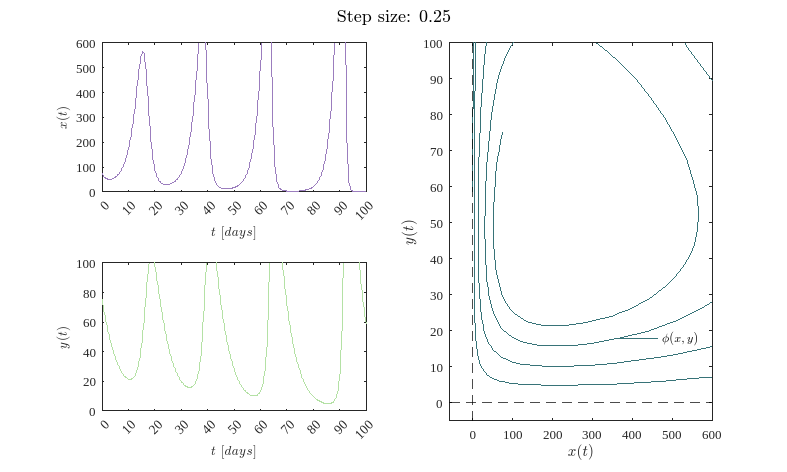

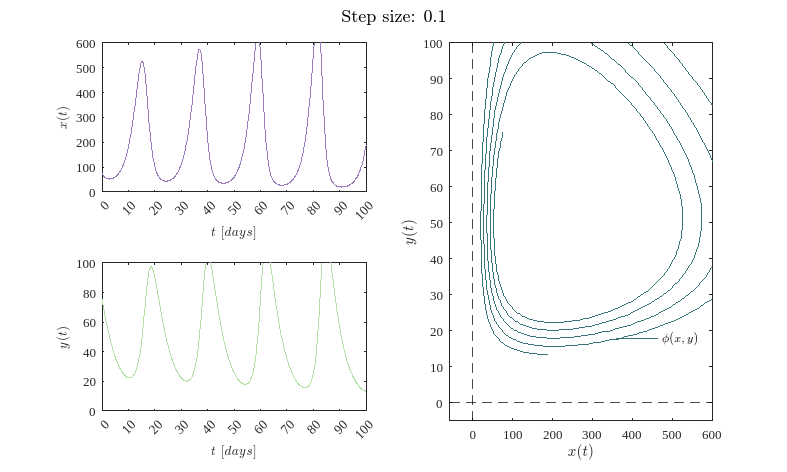

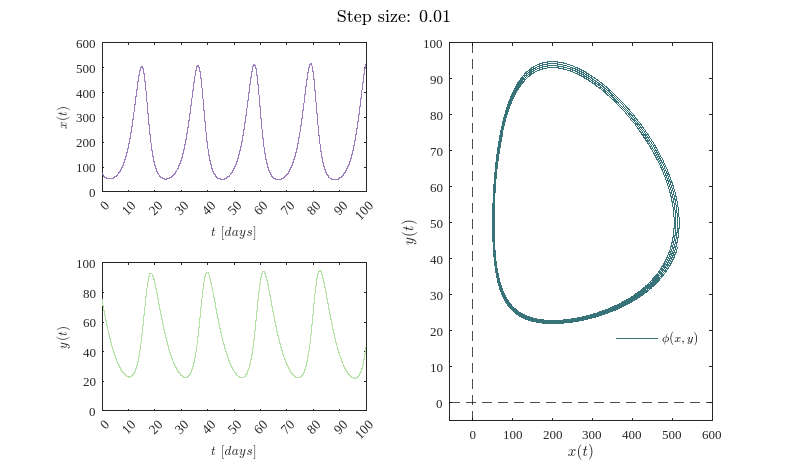

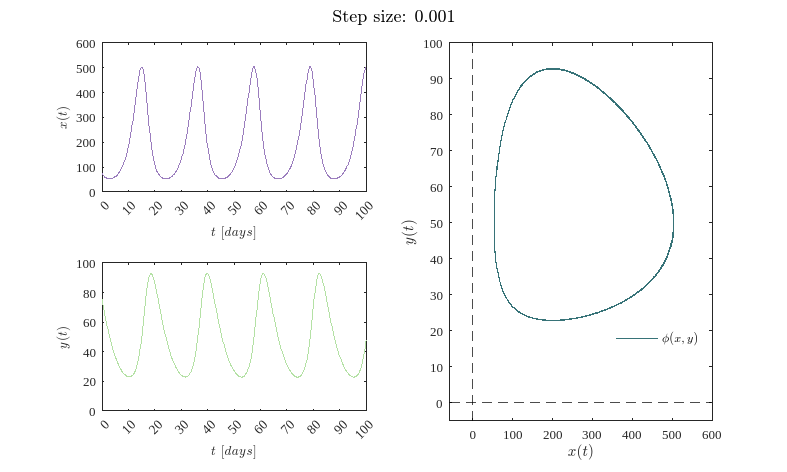

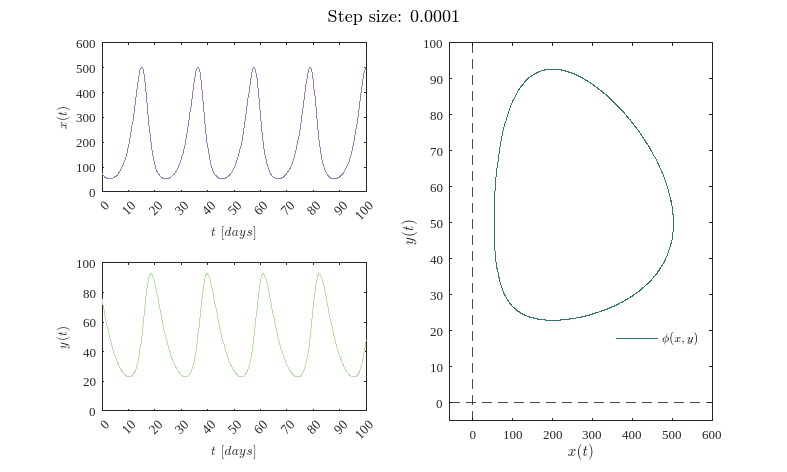

dt = [2,1,0.5,0.25,1E-1,1E-2,1E-3,1E-4,1E-5];
for i = 1:numel(dt)
    [t,x,y] = sys_Euler(x0,y0,dt(i),tend,P);
    plotEDOs(t,x,y,P,dt(i))
    exportgraphics(gcf,['Lotka-Volterra Euler',num2str(dt(i)),'.pdf'],'ContentType','vector')
end

## Solution by Heun's method

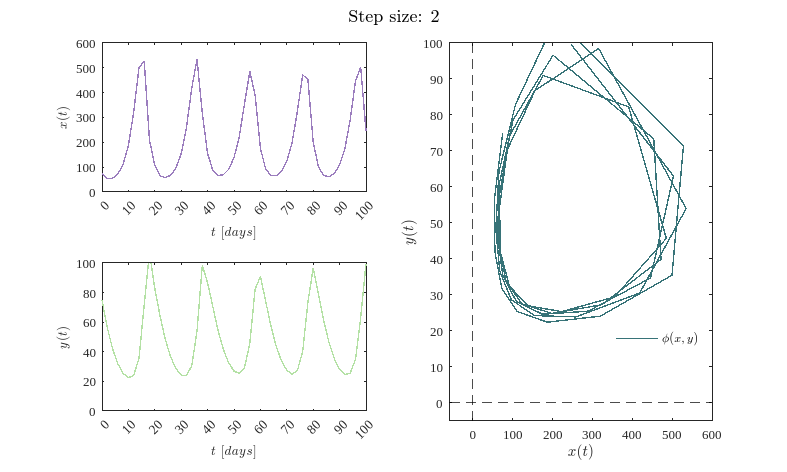

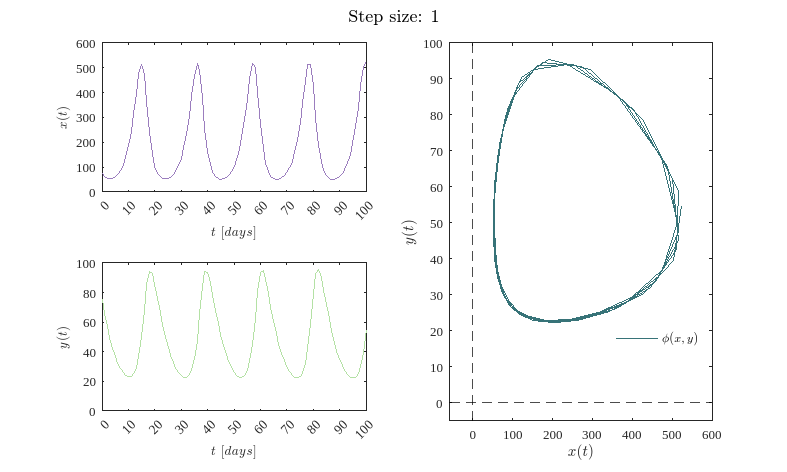

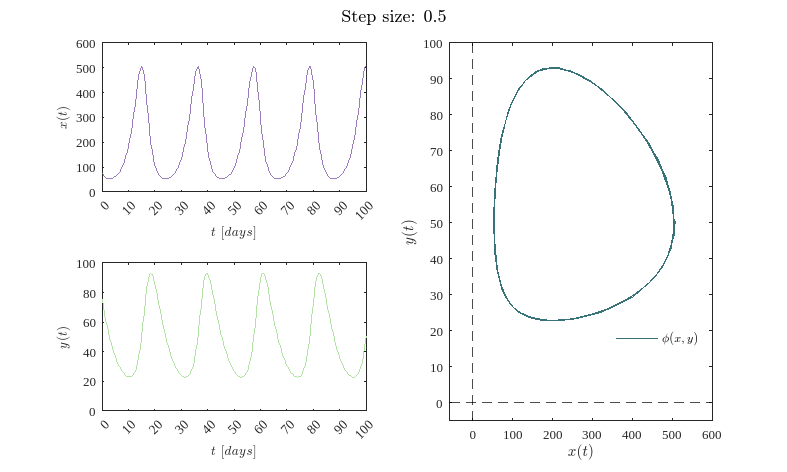

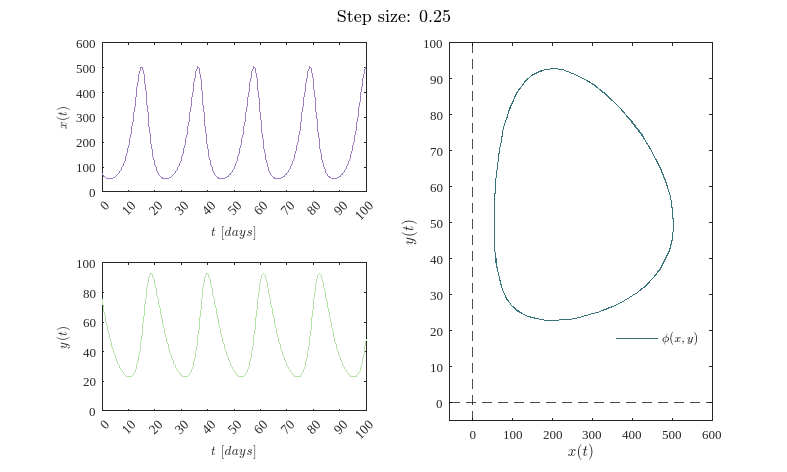

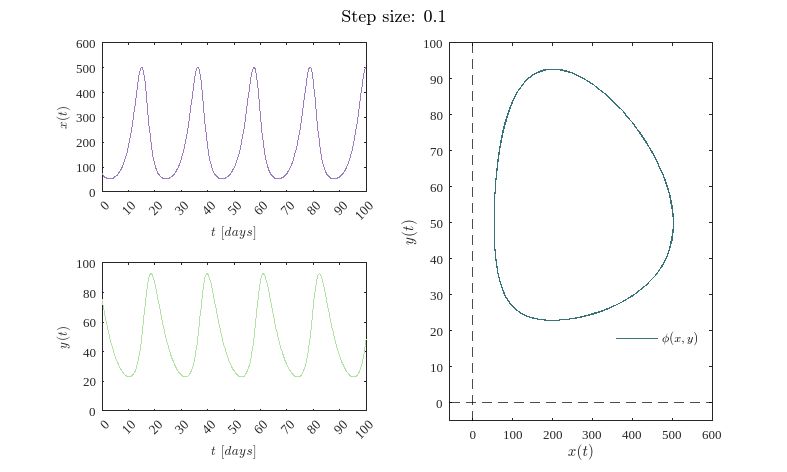

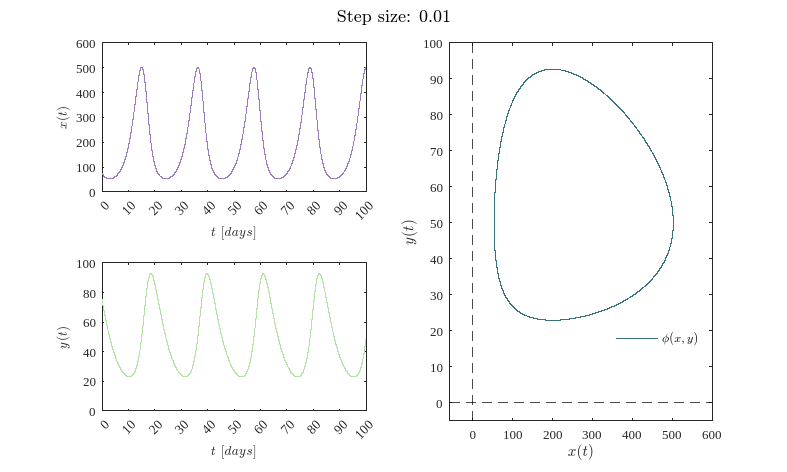

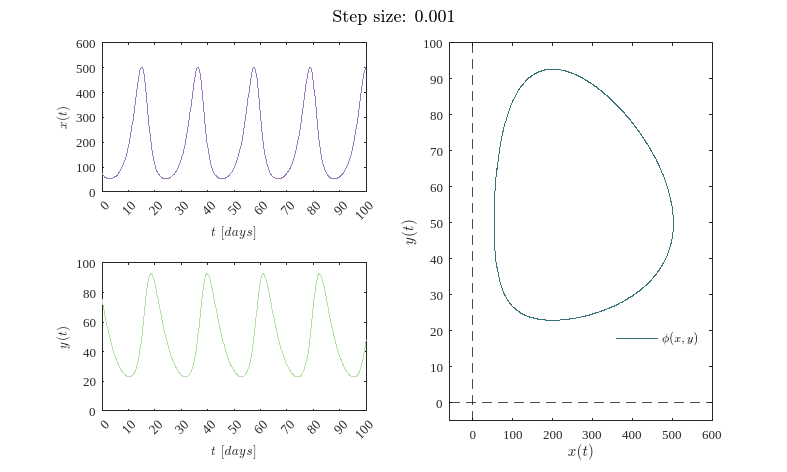

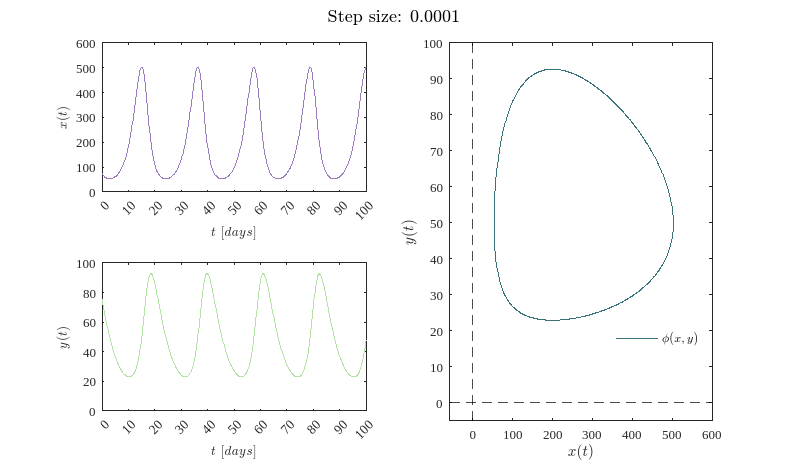

dt = [2,1,0.5,0.25,1E-1,1E-2,1E-3,1E-4,1E-5];
for i = 1:numel(dt)
    [t,x,y] = sys_Heun(x0,y0,dt(i),tend,P);
    plotEDOs(t,x,y,P,dt(i))
    exportgraphics(gcf,['Lotka-Volterra Heun',num2str(dt(i)),'.pdf'],'ContentType','vector')
end

## Simulink

file = 'System';
sim(file);
parameters.StopTime = '100';

### Solution by ode15s [Stiff solver]

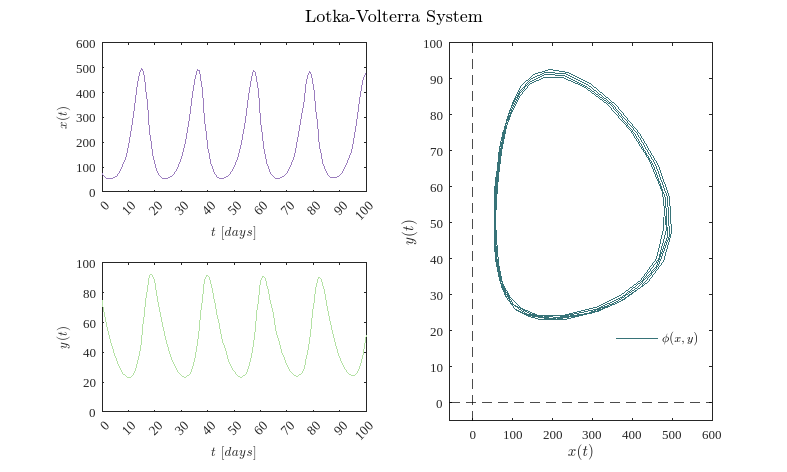

parameters.Solver = 'ode15s';
s15s = sim(file,parameters);
plotEDOs(s15s.t,s15s.x,s15s.y,P,0)
exportgraphics(gcf,'Lotka-Volterra ode15s.pdf','ContentType','vector')

% disp(diff(s15s.t));

### Solution by ode23s [Stiff solver]

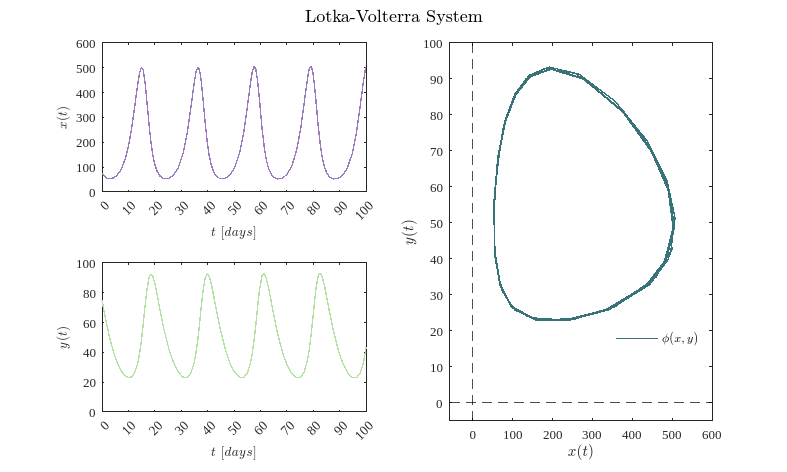

parameters.Solver = 'ode23s';
s23s = sim(file,parameters);
plotEDOs(s23s.t,s23s.x,s23s.y,P,0)
exportgraphics(gcf,'Lotka-Volterra ode23s.pdf','ContentType','vector')

% disp(diff(s23s.t));

### Solution by ode23t [Stiff solver]

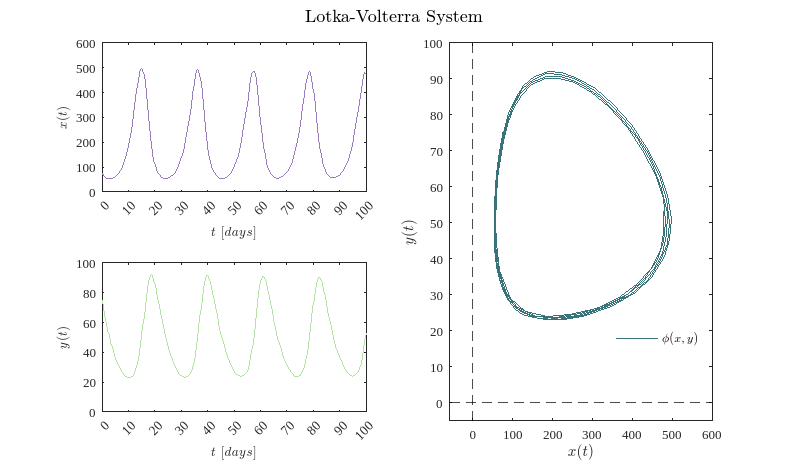

parameters.Solver = 'ode23t';
s23t = sim(file,parameters);
plotEDOs(s23t.t,s23t.x,s23t.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode23t.pdf'],'ContentType','vector')

% disp(diff(s23t.t));

### Solution by ode23tb [Stiff solver]

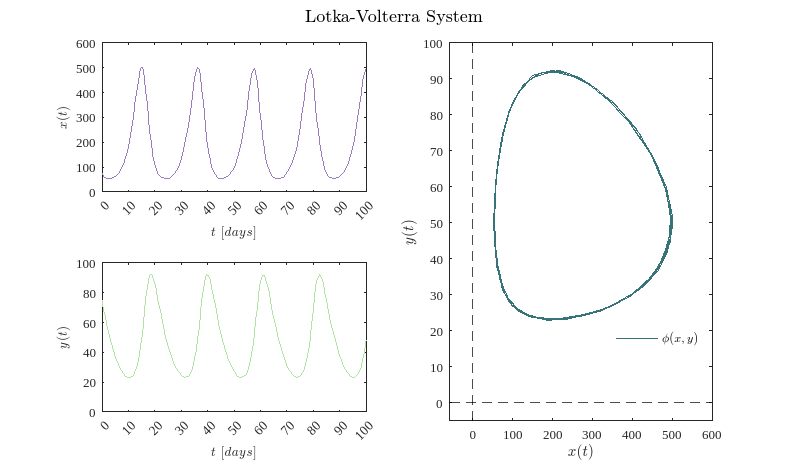

parameters.Solver = 'ode23tb';
s23tb = sim(file,parameters);
plotEDOs(s23tb.t,s23tb.x,s23tb.y,P,0)
exportgraphics(gcf,'Lotka-Volterra ode23tb.pdf','ContentType','vector')

% disp(diff(s23tb.t));

### Solution by ode45 [Nonstiff solver]

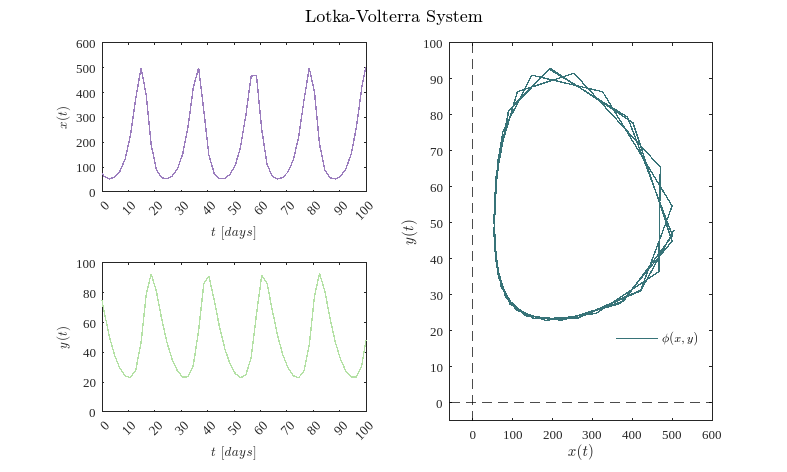

parameters.Solver = 'ode45';
s45 = sim(file,parameters);
plotEDOs(s45.t,s45.x,s45.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode45.pdf'],'ContentType','vector')

% disp(diff(s45.t));

### Solution by ode23 [Nonstiff solver]

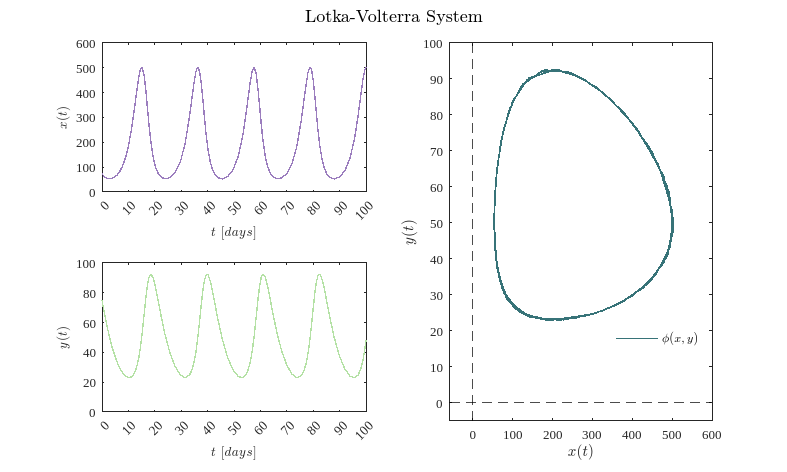

parameters.Solver = 'ode23';
s23 = sim(file,parameters);
plotEDOs(s23.t,s23.x,s23.y,P,0)
exportgraphics(gcf,'Lotka-Volterra ode23.pdf','ContentType','vector')

% disp(diff(s23.t));

### Solution by ode113 [Nontiff solver]

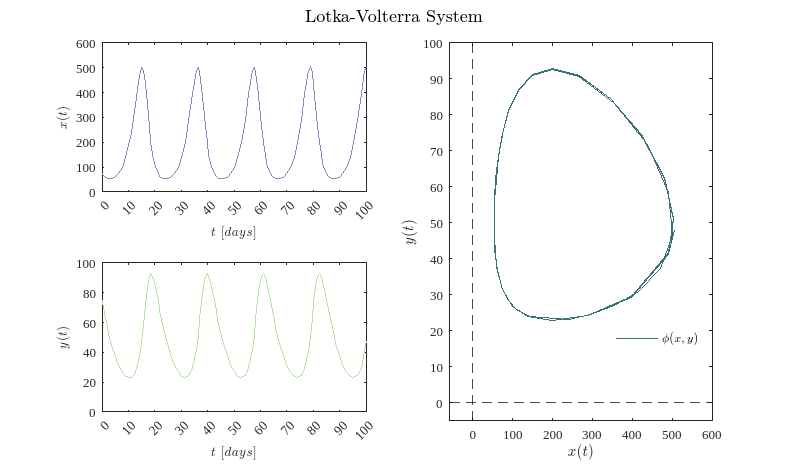

parameters.Solver = 'ode113';
s113 = sim(file,parameters);
plotEDOs(s113.t,s113.x,s113.y,P,0)
exportgraphics(gcf,'Lotka-Volterra ode113.pdf','ContentType','vector')

% disp(diff(s113.t));

Con base en las simulaciones numéricas, se concluye que el sistema de Lotka-Volterra es nonstiff,  ya que el solucionador s23tb requierió de intervalos de tiempo más pequeños para lograr una mejor aproximación. Esto se puede comprobar evaluando la diferencia entre los tiempos utilizados por el solucionador mediante la línea de código: diff(s113.t). Además, al analizar la trayectoria en el espacio de estados obtenida con este solucionador, se observa un comportamiento más estable.

[1] L. Petzold. "Automatic selection of methods for solving stiff and nonstiff systems of ordinary differential equations". *SIAM journal on scientific and statistical computing*, vol. *4, issue *1, pp. 136-148, 1983.

[2] MathWorks. (n.d). Stiff Differential Equations. [Online]. Available: [https://la.mathworks.com/company/technical-articles/stiff-differential-equations.html](https://la.mathworks.com/company/technical-articles/stiff-differential-equations.html)

## Equilibrium points and Jacobian matrix

clc; clear; close all; warning('off','all')
syms x y alpha beta delta gamma
dx = alpha*x - beta*x*y;
dy = delta*x*y - gamma*y;
J = jacobian([dx,dy],[x,y]);
fprintf('Jacobian matrix of the Lotka-Volterra system:'); disp(J)

Jacobian matrix of the Lotka-Volterra system:

$$\left(\begin{array}{cc} \alpha -\beta \,y & -\beta \,x\\ \delta \,y & \delta \,x-\gamma \end{array}\right)$$

dx = alpha*x - beta*x*y == 0;
dy = delta*x*y - gamma*y == 0;
edos = solve([dx,dy],[x,y]);
fprintf(['The Lotka-Volterra system has ', num2str(length(edos.x)), ' equilibrium points.']);

The Lotka-Volterra system has 2 equilibrium points.

X0 = edos.x(1); Y0 = edos.y(1);
X1 = edos.x(2); Y1 = edos.y(2);
syms x0 y0 x1 y1
fprintf('Equilibrium points of the Lotka-Volterra system:'); disp([x0,y0,X0,Y0]); disp([x1,y1,X1,Y1])

Equilibrium points of the Lotka-Volterra system:

$$\left(\begin{array}{cccc} x_{0} & y_{0} & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{1} & y_{1} & \frac{\gamma }{\delta } & \frac{\alpha }{\beta } \end{array}\right)$$

clear alpha beta delta gamma
alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
disp('(x0,y0) = (0,0)'); disp(['(x1,y1) = (', num2str(gamma/delta),',',num2str(alpha/beta),')'])

(x0,y0) = (0,0)
(x1,y1) = (200,50)


## Local stability

clc; clear; close all; warning('off','all')
alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
syms x y
dx = alpha*x - beta*x*y == 0;
dy = delta*x*y - gamma*y == 0;
edos = solve([dx,dy],[x,y]);
x0 = double(edos.x(1)); y0 = double(edos.y(1));
x1 = double(edos.x(2)); y1 = double(edos.y(2));
clear x y
x = [x0;x1]; y = [y0;y1];
var = {'(x0,y0)';'(x1,y1)'};
Equilibria = table(x,y,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye'};
fprintf('Equilibrium points of the Lotka-Volterra system:\n'); disp(Equilibria)

Equilibrium points of the Lotka-Volterra system:
               xe     ye
               ___    __

    (x0,y0)      0     0
    (x1,y1)    200    50



L = zeros(length(x),length(x));
for i = 1:length(x)
    J = [alpha - beta*y(i),   -beta*x(i);
                 delta*y(i),  delta*x(i)-gamma]
    L(i,:) = eig(J);
end

J =     0.5000         0
         0   -0.2000


J =          0   -2.0000
    0.0500         0


L1 = L(:,1); L2 = L(:,2);
Lambdas = table(L1,L2,'RowNames',var);
disp('Eigen values of the Jacobian matrix evaluated at each equilibrium point:'); disp(Lambdas)

Eigen values of the Jacobian matrix evaluated at each equilibrium point:
                    L1               L2     
               _____________    ____________

    (x0,y0)    -0.2+0i          0.5+0i      
    (x1,y1)       0+0.31623i      0-0.31623i



Con base al análisis matemático, se determina que, bajo las condiciones iniciales $\left(x_0 ,y_0 \right)$, el sistema es inestable, ya que $\lambda_1$ y $\lambda_2$ son reales y tienen signo opuesto, lo que quiere decir que las trayectorias divergen del punto de equilibrio. Mienteas que, bajo las condiciones iniciales $\left(x_1 ,y_1 \right)$, la estabilidad se clasifica como un caso marginal, específicamente centro,, lo que quiere decir que..

## Equilibrium points

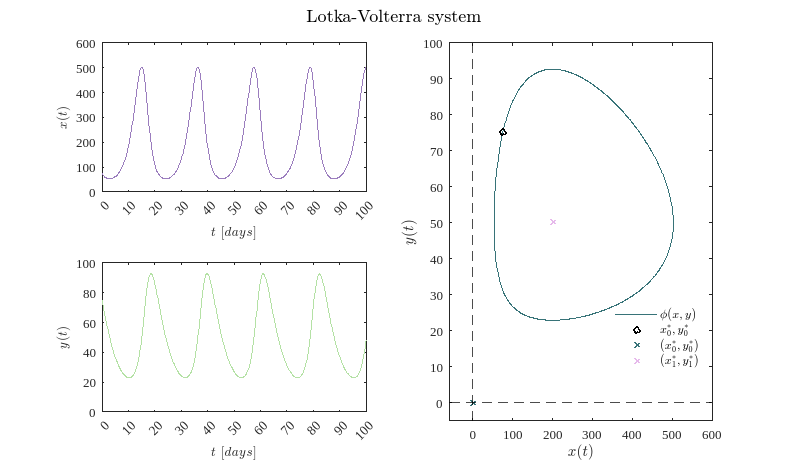

alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
P = [alpha,beta,delta,gamma];
x0 = 75; y0 = 75; tend = 100;
dt = 1E-4;
[t,x,y] = sys_Heun(x0,y0,dt,tend,P); % 1
plotEDOs(t,x,y,P,dt); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex') % 2
exportgraphics(gcf,'Lotka-Volterra Equilibria.pdf','ContentType','vector') % 3

## Data fitting

clc; clear; close all; warning('off','all')

### Raw data

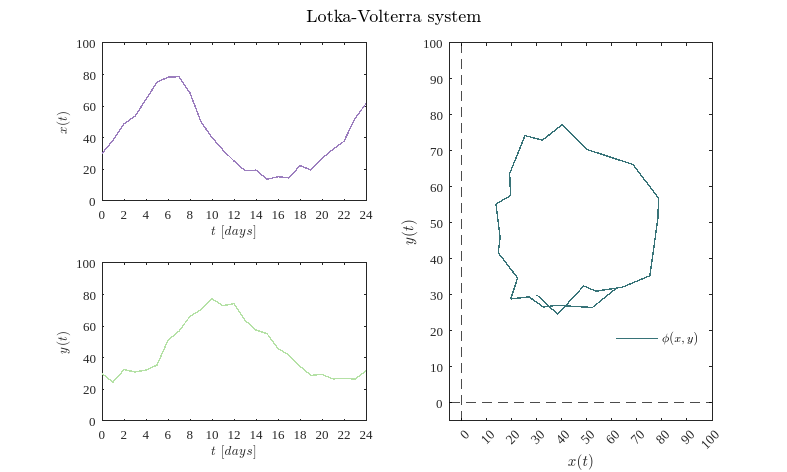

sys = readmatrix('data.xlsx');
to = round(sys(:,1)); xo = sys(:,2); yo = sys(:,3);
% T = array2table([t,x,y], 'VariableNames',{'t','x','y'}); disp(T)
alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
P = [alpha,beta,delta,gamma];
plotEDOsFit(to,xo,yo,P); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf,'Datta Fitting Lotka-Volterra.pdf','ContentType','vector')

### Smooth data

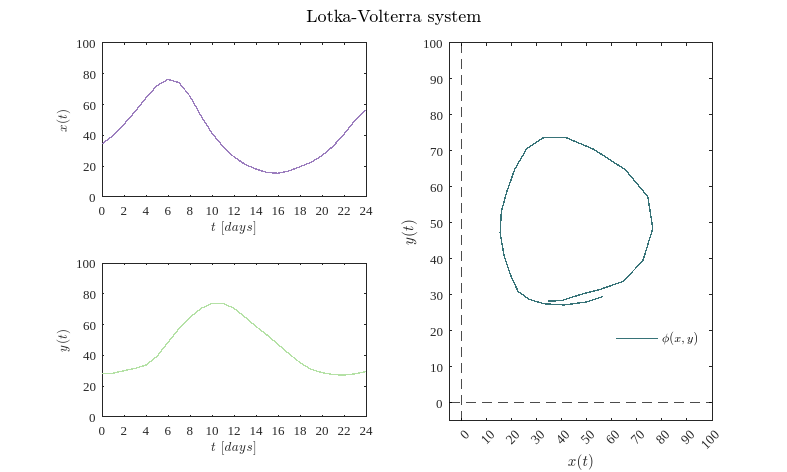

xo = smoothdata(xo,'gaussian',5);
yo = smoothdata(yo,'gaussian',5);
plotEDOsFit(to,xo,yo,P); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf,'Datta Fitting Lotka-Volterra (Smooth).pdf','ContentType','vector')

### Fit data

P0 = [1;0.01;0.01;0.1];
mdl = variant(to,xo,yo,P0);


Sample size (n): 25
Parameters to be estimated (pars): 4
Degrees of freedom: 46
Significance level (alpha): 0.05
t-Student value: 2.0129
Adjusted R-squared: 0.99289
Corrected AIC (n/pars < 40): 190.4761

    Parameters    Estimate         SE           MoE                 CI95               pvalue  
    __________    _________    __________    __________    ______________________    __________

      alpha         0.42674     0.0071089       0.01431      0.41243      0.44105    2.4161e-45
      beta        0.0089406    0.00017641    0.00035509    0.0085855    0.0092957    5.1873e-42
      delta       0.0052924     0.0001028    0.00020693    0.0050855    0.0054993    2.5534e-42
      gamma         0.21704     0.0043341     0.0087242      0.20831      0.22576     8.928e-42



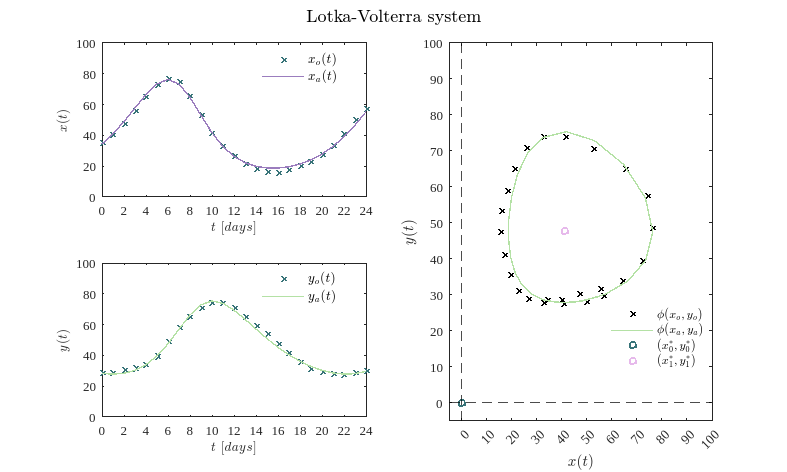

fa = mdl.Fitted;
fx = reshape(fa,[],2);
xa = fx(:,1); ya = fx(:,2);
P = table2array(mdl.Coefficients(:,1));
plotResults(to,[xo,xa],[yo,ya],P); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf,'Datta Fitting Lotka-Volterra (Fitted).pdf','ContentType','vector')

## Experimental data for Macrophages encounter *Mycobacterium Tuberculosis*

clc; clear; close all; warning('off','all')

### Raw data

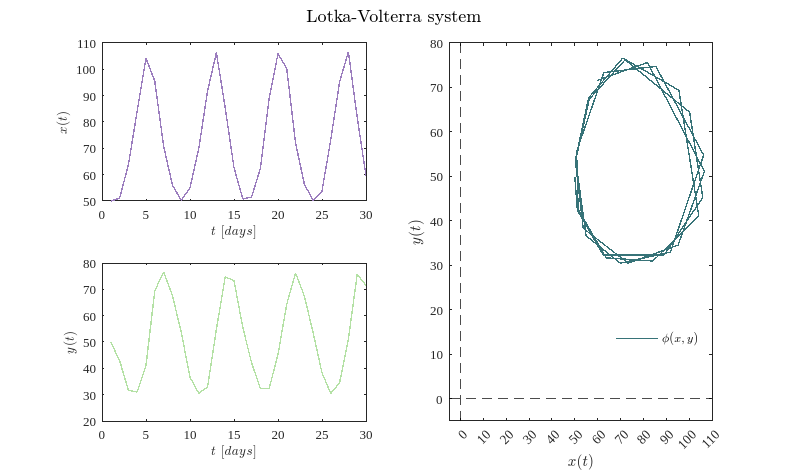

sys = readmatrix('dataSLV.xlsx');
to = round(sys(:,1)); xo = sys(:,2); yo = sys(:,3);
% T = array2table([t,x,y], 'VariableNames',{'t','x','y'}); disp(T)
alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
P = [alpha,beta,delta,gamma];
plotEDOsFit(to,xo,yo,P); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf,'Experimental Data Lotka-Volterra.pdf','ContentType','vector')

### Smooth data

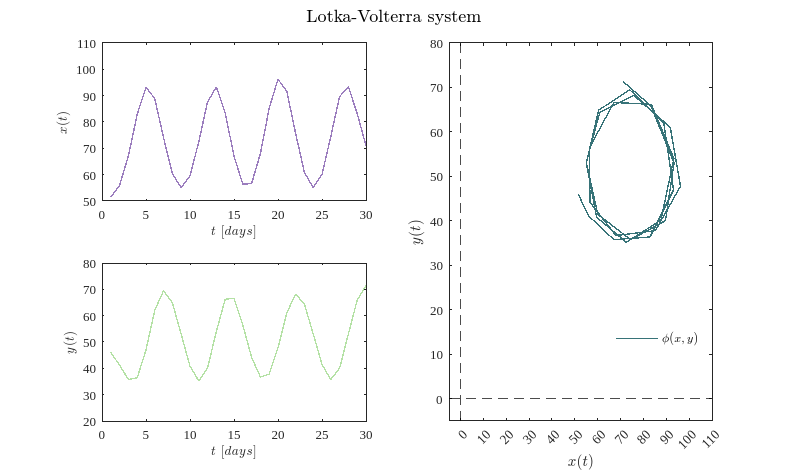

xo = smoothdata(xo,'gaussian',5);
yo = smoothdata(yo,'gaussian',5);
plotEDOsFit(to,xo,yo,P); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf,'Experimental Data Lotka-Volterra (Smooth).pdf','ContentType','vector')

### Fit data

P0 = [1.5; 0.01; 0.0045; 0.78];
mdl = variant(to,xo,yo,P0);


Sample size (n): 30
Parameters to be estimated (pars): 4
Degrees of freedom: 56
Significance level (alpha): 0.05
t-Student value: 2.0032
Adjusted R-squared: 0.77539
Corrected AIC (n/pars < 40): 428.2669

    Parameters    Estimate       SE           MoE               CI95              pvalue  
    __________    ________    _________    _________    ____________________    __________

      alpha        0.70027     0.098483      0.19729     0.50298     0.89755    2.2729e-09
      beta        0.015191    0.0021545    0.0043161    0.010875    0.019507    2.8548e-09
      delta       0.012604    0.0019063    0.0038187    0.008785    0.016422    1.5131e-08
      gamma        0.88835      0.12935      0.25912     0.62923      1.1475    5.7219e-09



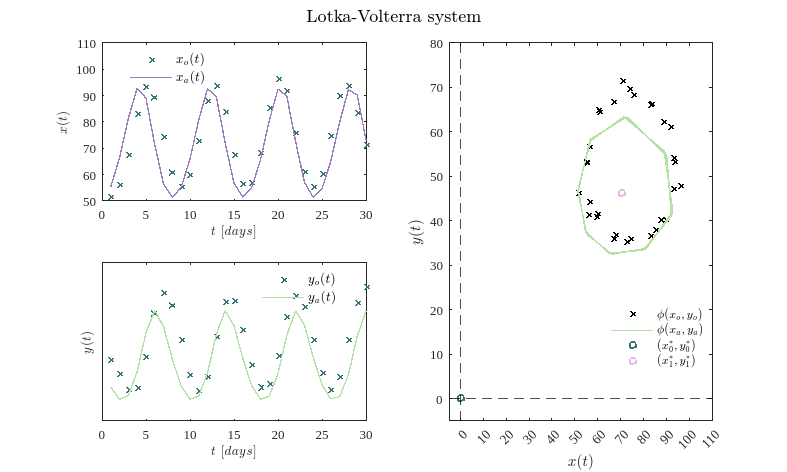

fa = mdl.Fitted;
fx = reshape(fa,[],2);
xa = fx(:,1); ya = fx(:,2);
P = table2array(mdl.Coefficients(:,1));
plotResults(to,[xo,xa],[yo,ya],P); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf,'Experimental Datta Fitting Lotka-Volterra (Fitted).pdf','ContentType','vector')

## Functions

### Euler's method

function [t,x,y] = sys_Euler(x0,y0,dt,tend,P)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    n = round(tend/dt);
    t = (0:dt:tend)';
    x = zeros(length(t),1); x(1) = x0;
    y = zeros(length(t),1); y(1) = y0;

    for i = 1:n
        x(i+1) = x(i) + (alpha*x(i) - beta*x(i)*y(i))*dt;
        y(i+1) = y(i) + (delta*x(i)*y(i) - gamma*y(i))*dt;
    end
end

### Heun's method

function [t, x, y] = sys_Heun(x0,y0,dt,tend,P)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    n = round(tend/dt);
    t = (0:dt:tend)';
    x = zeros(length(t),1); x(1) = x0;
    y = zeros(length(t),1); y(1) = y0;

    for i = 1:n
        [fx,fy] = f(x(i),y(i)); % Evalúa la función f(x,y) en el valor actual x(i) y(i).
        xn = x(i) + fx*dt; % Método de Euler para obtener un valor provisional xn
        yn = y(i) + fy*dt; % Método de Euler para obtener un valor provisional yn
        [fxn,fyn] = f(xn,yn); % Evalúa f(x,y) en el valor actual xn yn
        x(i+1) = x(i) + (fx + fxn)*dt/2; % Método de Heun para x
        y(i+1) = y(i) + (fy + fyn) * dt/2; % Método de Heun para y
    end

    function [dx,dy] = f(x,y) % Función llamada f, que toma un argumento de entrada x1 y devuelve un valor de salida dx1.
        dx = alpha*x - beta*x*y;
        dy = delta*x*y - gamma*y;
    end
end

### Solutions and trajectories

function plotEDOs(t,x,y,P,dt)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',[0.6078, 0.4902, 0.7451])
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 600]); yticks(0:100:600)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',[0.7059, 0.8824, 0.6471])
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,[2,4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(x,y,'-','LineWidth',1,'Color',[0.2157, 0.4510, 0.4706])
    plot(x(1),y(1),'o','MarkerSize',4,'LineWidth',1.5,'Color',[0, 0, 0]) % 1
    plot(0,0,'x','MarkerSize',5,'LineWidth',1.5,'Color',[0.2157, 0.4509, 0.4706]) % 2
    plot(gamma/delta,alpha/beta,'x','MarkerSize',5,'LineWidth',1.5,'Color',[0.9019, 0.7255, 0.9216]) % 3
    xlabel('$x(t)$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([-60 600]); xticks(0:100:600)
    ylim([-5 100]); yticks(0:10:100)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    L = legend('$\phi(x,y)$','$x^*_0,y^*_0$','$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$'); % 4
    % L = legend('$\phi(x,y)$'); % 5
    set(L,'Interpreter','Latex','Location','none','Position',[0.778,0.263,0.115,0.041],'Box','Off')
    
    if dt == 0
        ttl = 'Lotka-Volterra System';
        sgtitle(ttl,'Interpreter','Latex');
    else
        ttl = ['Step size: ',num2str(dt)];
        sgtitle(ttl,'Interpreter','Latex');
    end
end

function plotEDOsFit(t,x,y,P)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',[0.6078, 0.4902, 0.7451])
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    % xlim([0 24]); xticks(0:2:24)
    % ylim([0 100]); yticks(0:20:100)
    xlim([0 30]); xticks(0:5:30)
    ylim([50 110]); yticks(50:10:110)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',[0.7059, 0.8824, 0.6471])
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    % xlim([0 24]); xticks(0:2:24)
    % ylim([0 100]); yticks(0:20:100)
    xlim([0 30]); xticks(0:5:30)
    ylim([20 80]); yticks(20:10:80)

    subplot(2,2,[2,4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(x,y,'-','LineWidth',1,'Color',[0.2157, 0.4510, 0.4706])
    xlabel('$x(t)$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    % xlim([-5 100]); xticks(0:10:100)
    % ylim([-5 100]); yticks(0:10:100)
    xlim([-5 110]); xticks(0:10:110)
    ylim([-5 80]); yticks(0:10:80)

    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    L = legend('$\phi(x,y)$');
    set(L,'Interpreter','Latex','Location','none','Position',[0.778,0.263,0.115,0.041],'Box','Off')
end

function plotResults(t,x,y,P)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',[0.2157, 0.4509, 0.4706])
    plot(t,x(:,2),'-','LineWidth',1,'Color',[0.6078, 0.4902, 0.7451])
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    % xlim([0 24]); xticks(0:2:24)
    % ylim([0 100]); yticks(0:20:100)
    xlim([0 30]); xticks(0:5:30)
    ylim([50 110]); yticks(50:10:110)
    L = legend('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',[0.2157, 0.4509, 0.4706])
    plot(t,y(:,2),'-','LineWidth',1,'Color',[0.7059, 0.8824, 0.6471])
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    % xlim([0 24]); xticks(0:2:24)
    % ylim([0 100]); yticks(0:20:100)
    xlim([0 30]); xticks(0:5:30)
    ylim([25 80]); yticks(20:10:8)
    L = legend('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')

    subplot(2,2,[2,4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(x(:,1),y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',[0, 0, 0])
    plot(x(:,2),y(:,2),'-','LineWidth',1,'Color',[0.7059, 0.8824, 0.6471])
    plot(0,0,'o','MarkerSize',5,'LineWidth',1.5,'Color',[0.2157, 0.4509, 0.4706])
    plot(gamma/delta,alpha/beta,'o','MarkerSize',5,'LineWidth',1.5,'Color',[0.9019, 0.7255, 0.9216])
    xlabel('$x(t)$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    % xlim([-5 100]); xticks(0:10:100)
    % ylim([-5 100]); yticks(0:10:100)
    xlim([-5 110]); xticks(0:10:110)
    ylim([-5 80]); yticks(0:10:80)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    L = legend('$\phi(x_o,y_o)$','$\phi(x_a,y_a)$','$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$');
    set(L,'Interpreter','Latex','Location','none','Position',[0.778,0.263,0.115,0.041],'Box','Off')
end

### Nonlinear regression algorithm

function mdl = variant(to,xo,yo,P0)
    x0 = xo(1); y0 = yo(1);
    to = [to;to];
    fo = [xo;yo];

    function fi = model(p,t)
        alpha = p(1); beta = p(2); delta = p(3); gamma = p(4);
        dt = 1E-2;
        t = reshape(t,[],2); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = x0;
        y = zeros(length(time),1); y(1) = y0;

        for i = 1:n
            [fx,fy] = f(x(i),y(i)); % Evalúa la función f(x,y) en el valor actual x(i) y(i).
            xn = x(i) + fx*dt; % Método de Euler para obtener un valor provisional xn
            yn = y(i) + fy*dt; % Método de Euler para obtener un valor provisional yn
            [fxn,fyn] = f(xn,yn); % Evalúa f(x,y) en el valor actual xn yn
            x(i+1) = x(i) + (fx + fxn)*dt/2; % Método de Heun para x
            y(i+1) = y(i) + (fy + fyn) * dt/2; % Método de Heun para y
        end

        function [dx,dy] = f(x,y) % Función llamada f, que toma un argumento de entrada x1 y devuelve un valor de salida dx1.
            dx = alpha*x - beta*x*y;
            dy = delta*x*y - gamma*y;
        end

        xi = zeros(length(t),1);
        yi = zeros(length(t),1);

        for j = 1:length(t)
            k = abs(time - t(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
        end

        fi = [xi;yi];
    end

    mdl = fitnlm(to,fo,@model,P0);
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['alpha';'beta ';'delta';'gamma'];
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);
    fprintf(['\nSample size (n): ', num2str(numel(xo))])
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nAdjusted R-squared: ', num2str(mdl.Rsquared.Adjusted)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
    
    disp(Results)
end